# Get Started with ROS in Simulink

This example shows how to use Simulink® blocks for ROS to send and receive messages from a local ROS network.

## Introduction

Simulink support for Robot Operating System (ROS) enables you to create Simulink models that work with a ROS network. ROS is a communication layer that allows different components of a robot system to exchange information in the form of *messages*. A component sends a message by *publishing* it to a particular *topic*, such as `/odometry`. Other components receive the message by *subscribing* to that topic.

Simulink support for ROS includes a library of Simulink blocks for sending and receiving messages for a designated topic. When you simulate the model, Simulink connects to a ROS network, which can be running on the same machine as Simulink or on a remote system. Once this connection is established, Simulink exchanges messages with the ROS network until the simulation is terminated. If Simulink Coder™ is installed, you can also generate C++ code for a standalone ROS component, or *node*, from the Simulink model.

This example shows how to:

- Set up the ROS environment

- Create and run a Simulink model to send and receive ROS messages

- Work with data in ROS messages

Prerequisites: [Create a Simple Model](docid:simulink_gs.bthii4g), [Get Started with ROS](docid:ros_ug.mw_cb3fdf75-613d-45b1-90e1-aad102b9a24a)

## Model

You will use Simulink to publish the `X` and `Y` location of a robot. You will also subscribe to the same location topic and display the received `X`,`Y` location. 

Enter the following command to open the completed [model](matlab:robotROSGetStartedExample) created in example.

open_system('robotROSGetStartedExample');

## Initialize ROS

Every ROS network has a *ROS master* that coordinates all the parts of the ROS network. For this example, use MATLAB® to create a ROS master on your local system. Simulink automatically detects and uses the local ROS master.

On the MATLAB command line, execute the following:

## Create a Publisher

Configure a block to send a `geometry_msgs/Point` message to a topic named `/location` (the "`/`" is standard ROS syntax).

- From the MATLAB Toolstrip, select **Home*** > ***Simulink** to open Simulink Start Page.

- On Simulink Start Page, under **Simulink**, click **Blank Model** to create and open a new Simulink Model.

- From the Simulink Toolstrip, select **Simulation*** > ***Library Browser** to open the Simulink Library Browser. Click on the** ROS Toolbox** tab (you can also type `roslib` in MATLAB command window). Select the **ROS** Library.

- Drag a **Publish** block to the model. Double-click on the block to configure the topic and message type.

- Select **Specify your own** for the **Topic source**, and enter `/location` in **Topic**.

- Click **Select** next to **Message type**. A pop-up window will appear. Select `geometry_msgs/Point` and click **OK **to close the pop-up window.

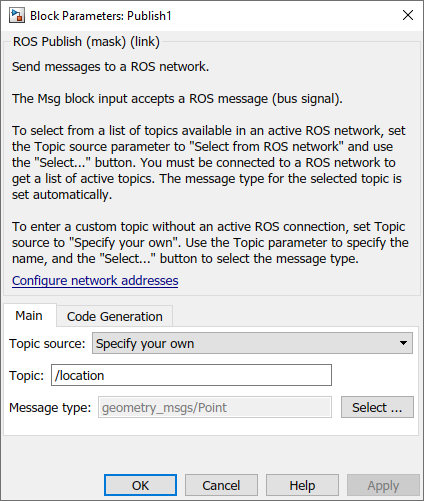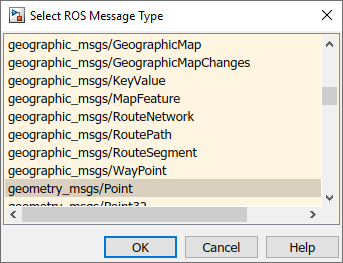

## Create a ROS Message

Create a blank ROS message and populate it with the `X` and `Y` location for the robot path. Then publish the updated ROS message to the ROS network.

A ROS message is represented as a *bus signal* in Simulink. A bus signal is a bundle of Simulink signals, and can also include other bus signals (see the [Simulink Bus Signals](docid:simulink_ref#example-slexBusExample) example for an overview). The ROS **Blank Message** block outputs a Simulink bus signal corresponding to a ROS message.

- Click **ROS Toolbox** tab in the Library Browser, or type `roslib` at the MATLAB command line. Select the **ROS** Library.

- Drag a **Blank Message** block to the model. Double-click on the block to open the block mask. 

- Click on **Select** next to the **Message type** box, and select `geometry_msgs/Point` from the resulting pop-up window. Click **OK** to close the block mask.

- From the **Simulink*** > ***Signal Routing** tab in the Library Browser, drag a **Bus Assignment** block.

- Connect the output port of the **Blank Message** block to the Bus input port of the **Bus Assignment** block. Connect the output port of the **Bus Assignment** block to the input port of **ROS Publish** block.

- Double-click on the **Bus Assignment** block. You should see `X`, `Y` and `Z` (the signals comprising a `geometry_msgs/Point` message) listed on the left. Select `??? signal1` in the right listbox and click **Remove**. Select both `X` and `Y` signals in the left listbox and click **Select**. Click **OK** to apply changes.

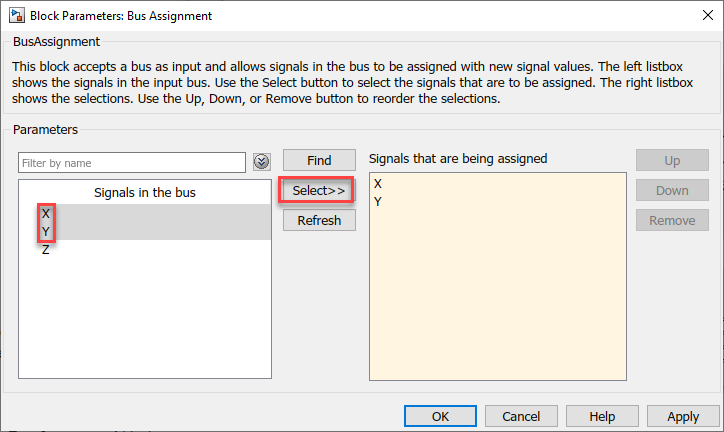

NOTE: If you do not see `X`, `Y` and `Z` listed, close the block mask for the Bus Assignment block, and under the **Modeling** tab*, *click **Update Model** to ensure that the bus information is correctly propagated. If you see the error, "Selected signal 'signal1' in the Bus Assignment block cannot be found", it indicates that the bus information has not been propagated. Close the Diagnostic Viewer, and repeat the above step.

You can now populate the bus signal with the robot location.

- From the **Simulink*** > ***Sources **tab in the Library Browser, drag two **Sine Wave** blocks into the model.

- Connect the output ports of each **Sine Wave** block to the assignment input ports `X` and `Y` of the **Bus Assignment** block.

- Double-click on the **Sine Wave** block that is connected to input port `X`. Set the **Phase** parameter to `-pi/2` and click **OK**. Leave the **Sine Wave** block connected to input port `Y` as default.

Your publisher should look like this:

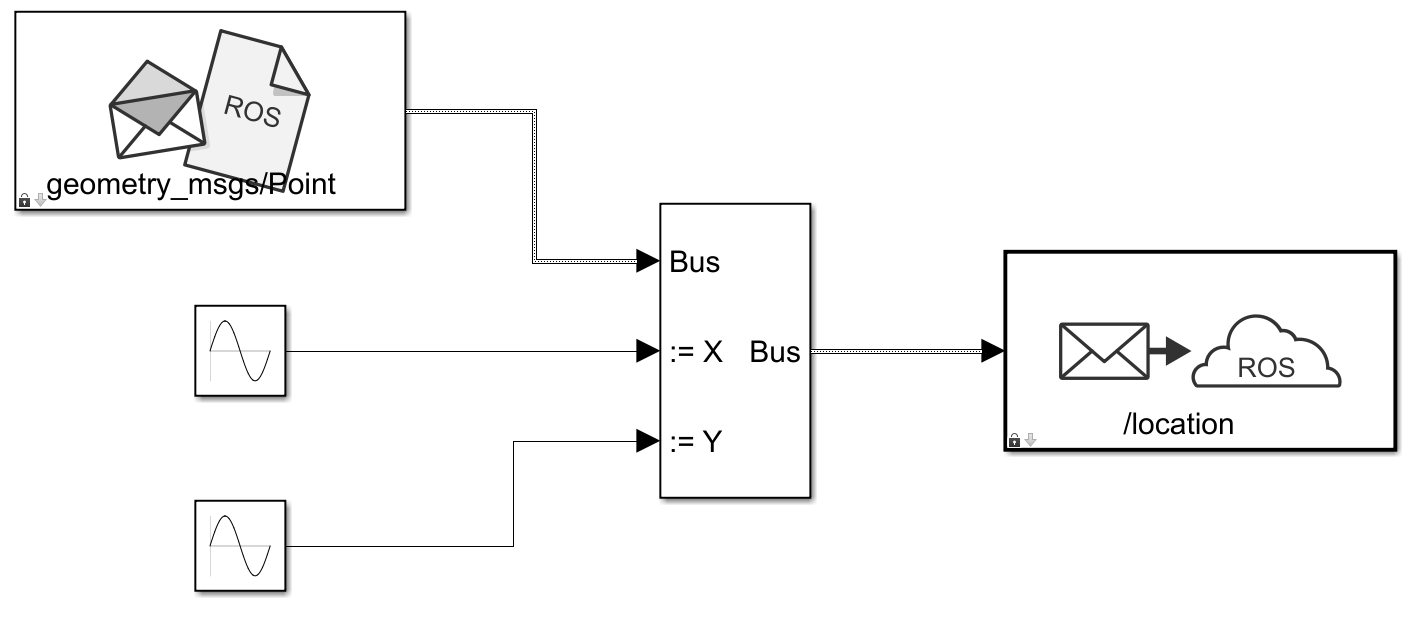

At this point, the model is set up to publish messages to the ROS network. You can verify this as follows:

- Under the **Simulation** tab, set the simulation stop time to `inf`.

- Click **Run** to start simulation. Simulink creates a dedicated ROS node for the model and a ROS publisher corresponding to the **Publish** block.

- While the simulation is running, type `rosnode` `list` in the MATLAB command window. This lists all the nodes available in the ROS network, and includes a node with a name like `/untitled_81473` (the name of the model along with a random number to make it unique).

- While the simulation is running, type `rostopic` `list` in the MATLAB command window. This lists all the topics available in the ROS network, and it includes `/location`.

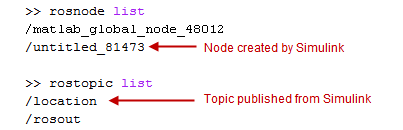

- Click **Stop** to stop the simulation. Simulink deletes the ROS node and ROS publisher. In general, the ROS node for a model and any associated publishers and subscribers are automatically deleted at the end of a simulation; no additional clean-up steps are required.

## Create a Subscriber

Use Simulink to receive messages sent to the `/location` topic. You will extract the `X` and `Y` location from the message and plot it in the `XY`-plane.

- From the **ROS Toolbox** tab in the Library Browser, drag a **Subscribe** block to the model. Double-click on the block.

- Select **Specify your own** in the **Topic source** box, and enter `/location` in the **Topic** box.

- Click **Select** next to the **Message type** box, and select `geometry_msgs/Point` from the pop-up window. Click **OK** to close the block mask.

The **Subscribe** block outputs a Simulink bus signal, so you need to extract the `X` and `Y` signals from it.

- From the **Simulink*** > ***Signal Routing** tab in the Library Browser, drag a **Bus Selector** block to the model.

- Connect the **Msg** output of the **Subscribe** block to the input port of the **Bus Selector** block.

- From the **Modeling** tab, select **Update Model** to ensure that the bus information is propagated. You may get an error, "Selected signal 'signal1' in the Bus Selector block 'untitled/Bus Selector' cannot be found in the input bus signal". This error is expected, and will be resolved by the next step.

- Double-click on the **Bus Selector** block. Select `??? signal1` and `??? signal2` in the right listbox and click **Remove**. Select both `X` and `Y` signals in the left listbox and click **Select**. Click **OK**.

The **Subscribe** block will output the most-recently received message for the topic on every time step. The **IsNew** output indicates whether the message has been received during the prior time step. For the current task, the **IsNew** output is not needed, so do the following:

- From the **Simulink*** > ***Sinks** tab in the Library Browser, drag a **Terminator** block to the model.

- Connect the **IsNew** output of the **Subscribe** block to the input of the **Terminator** block.

The remaining steps configure the display of the extracted `X` and `Y` signals. 

- From the **Simulink*** > ***Sinks** tab in the Library Browser, drag an **XY Graph** block to the model. Connect the output ports of the **Bus Selector** block to the input ports of the **XY Graph** block.

- From the **Simulink*** > ***Sinks** tab in the Library Browser, drag two **Display** blocks to the model. Connect each output of the **Bus Selector** block to each **Display** block.

- Save your model.

Your entire model should look like this:

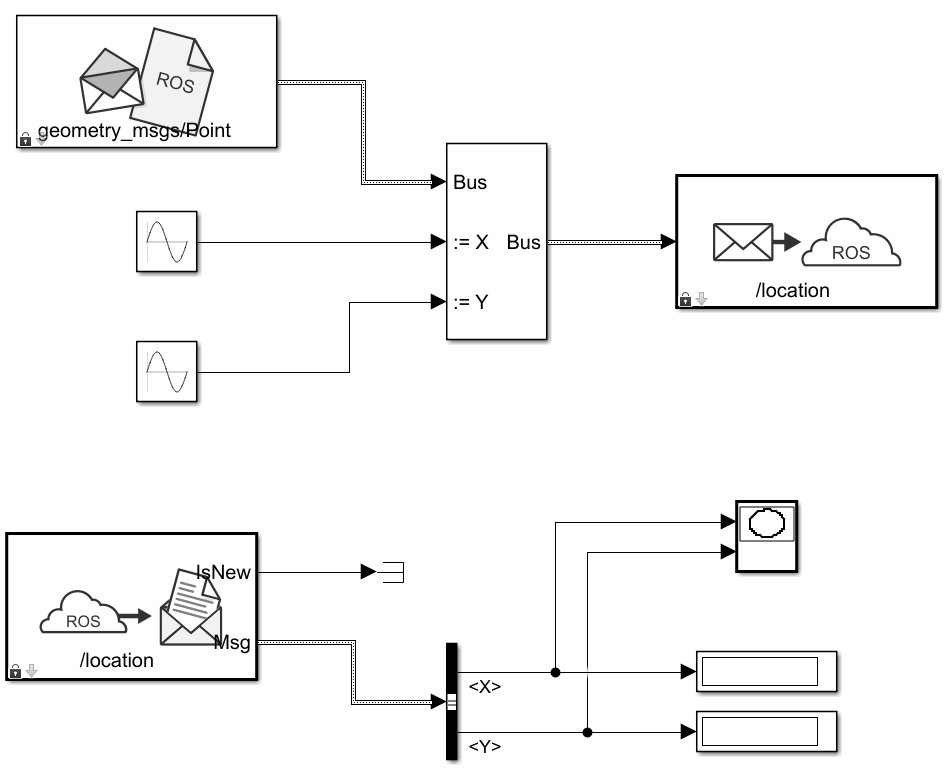

## Configure and Run the Model

- From the **Modeling** tab, select **Model Settings**. In the **Solver** pane, set **Type** to **Fixed-step** and **Fixed-step size** to `0.01`.

- Set simulation stop time to `10.0`. 

- Click **Run** to start simulation. An `XY` plot will appear.

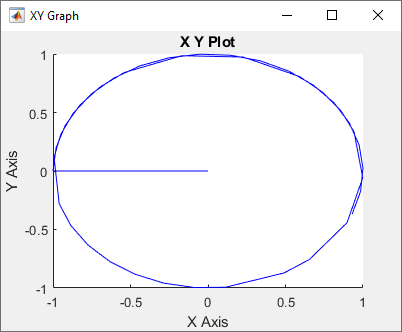

The first time you run the model in Simulink, the `XY` plot may look more jittery than the one above due to delays caused by loading ROS libraries. Once you rerun the simulation a few times, the plot should look smoother.

Note that the simulation **does not** work in actual or "real" time. The blocks in the model are evaluated in a loop that only simulates the progression of time, and is not intended to track actual clock time (for details, see [Simulation Loop Phase](docid:simulink_ug.f7-8261)).

## Modify the Model to React Only to New Messages

In the above model, the **Subscribe** block outputs a message (bus signal) on every time step; if no messages have been received at all, it outputs a blank message (i.e., a message with zero values). Consequently, the `XY` coordinates are initially plotted at `(0,0)`.

In this task, you will modify the model to use an **Enabled Subsystem**, so that it plots the location only when a new message is received (for more information, see [Using Enabled Subsystems](docid:simulink_ug.f4-84107)). A [pre-configured model](matlab:robotROSGetStartedExample) is included for your convenience.

- In the model, click and drag to select the **Bus Selector** block and **XY Graph** blocks. Right-click on the selection and select **Create Subsystem from Selection**.

- From the **Simulink*** > ***Ports & Subsystems** tab in the Library Browser, drag an **Enable** block into the newly-created subsystem.

- Connect the **IsNew** output of the **Subscribe** block to the enabled input of the subsystem as shown in the picture below. Delete the **Terminator** block. Note that the **IsNew** output is true only if a new message was received during the previous time step.

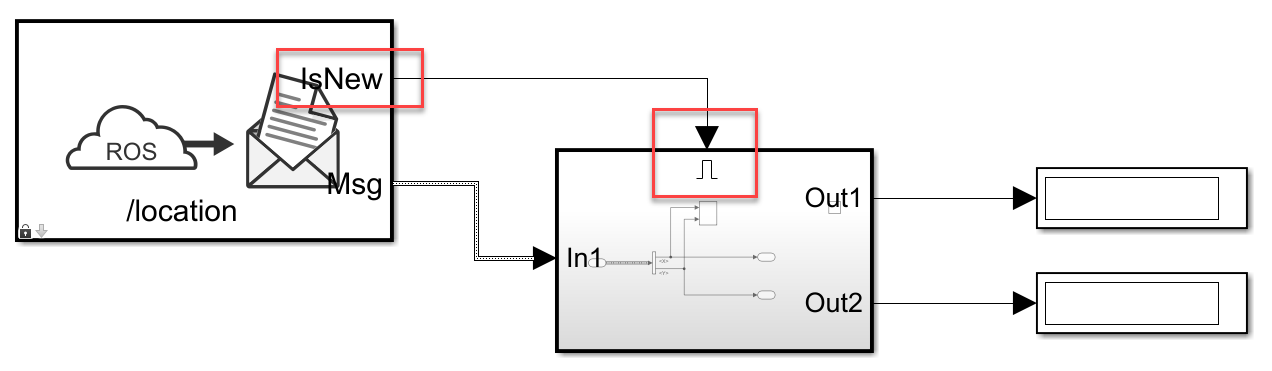

- Save your model. 

- Click **Run** to start simulation. You should see the following `XY` plot.

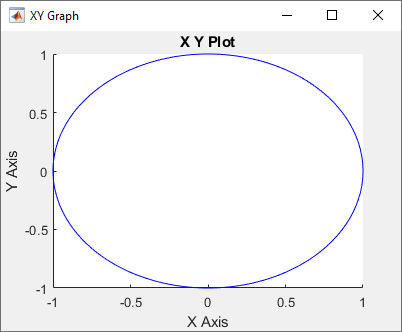

The blocks in the enabled subsystem are only executed when a new ROS message is received by the **Subscribe** block. Hence, the initial `(0,0)` value will not be displayed in the `XY` plot.

*Copyright 2014-2019 The MathWorks, Inc.*